Initializa transfer function

s = tf('s');
G = (s+5)/((-s+1)*(s+1000));
wc = 1100;

Obtain the desired loop shape using loopsyn.

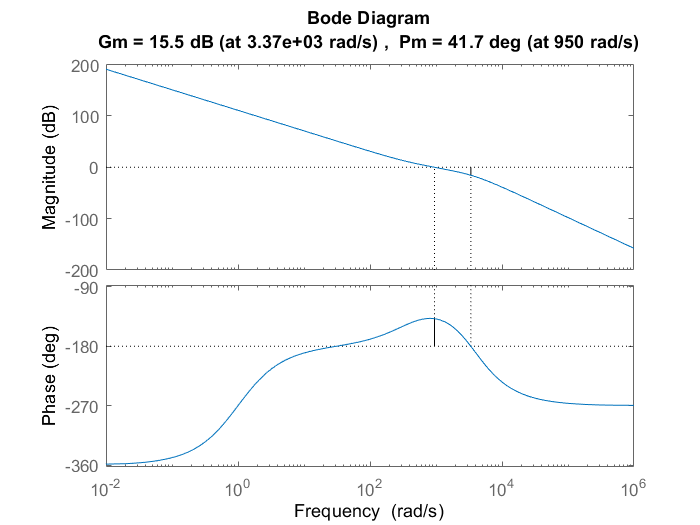

[K,CL,GAM] = loopsyn(G,wc^2/s^2);
[Gm,Pm,Wcg,Wcp] = margin(G*K);
margin(G*K)

bode magnitude plot for the sensitivity function.

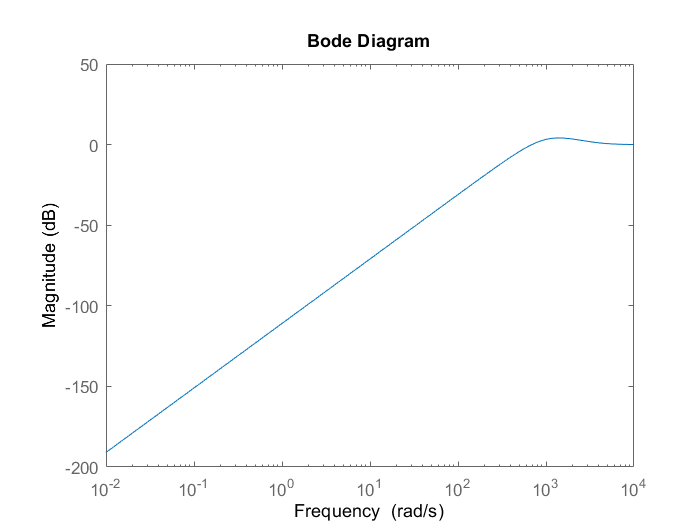

bodemag(1-CL)